# DataSet Quick Viewer (スピナー専用)

一度データの分布を確認した上で、外れ値データの削除は、手作業で繰り返して行う。

input: featuresテーブル：生振動データから特徴量として抽出されたもの

temp: tmp：ブッシング毎に分けるための一時テーブル

output: 

## X,Y Scatter plot（Y＝スピナー時間）

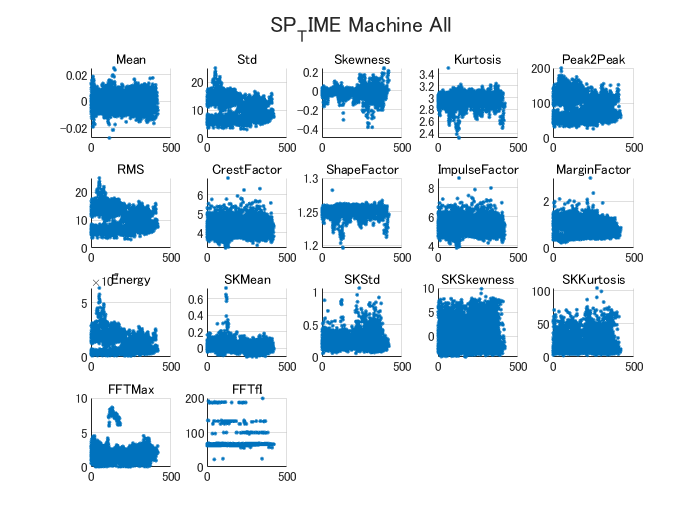

tmp = features;
figure;
t = tiledlayout ('flow',"TileSpacing","compact");         %t=tiledlayout (4,4);
title (t, "SP_TIME Machine All");
for i = 18:numel(tmp.Properties.VariableNames)
    nexttile;
    scatter(tmp.SP_TIME,tmp(:,i).(1),'.');
    title(tmp.Properties.VariableNames(i))
    grid on;
%               scatter(features.SP_TIME,features(:,i+j).(1),"blue",'.');
%                scatter(tmp.xTime,tmp(:,i+j).(1),'.');
%                gscatter(features.xTime,features(:,i+j).(1),features.BushingNo);
end
saveas (gcf, "Scatter SP_TIME spinner", "png");    
savefig ("Scatter SP_TIME spinner")

clear i j k t tmp bs;

## Line plot（注：テーブルのデータ順に表示）

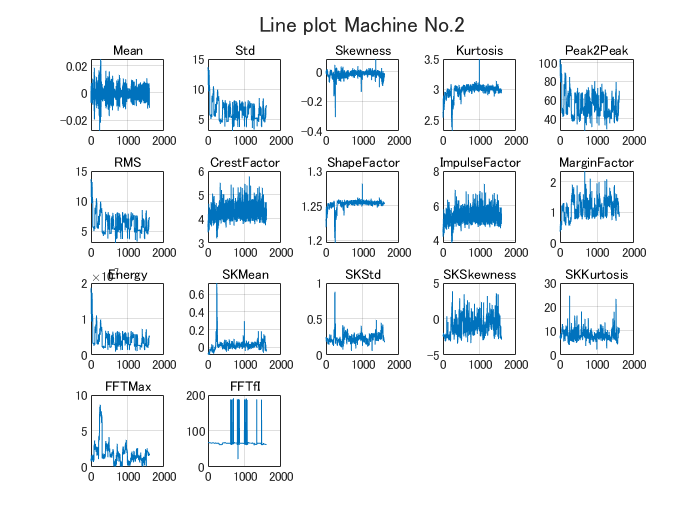

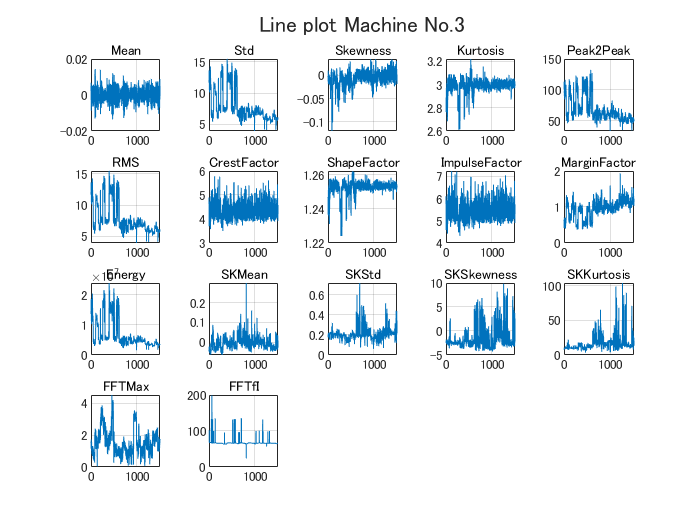

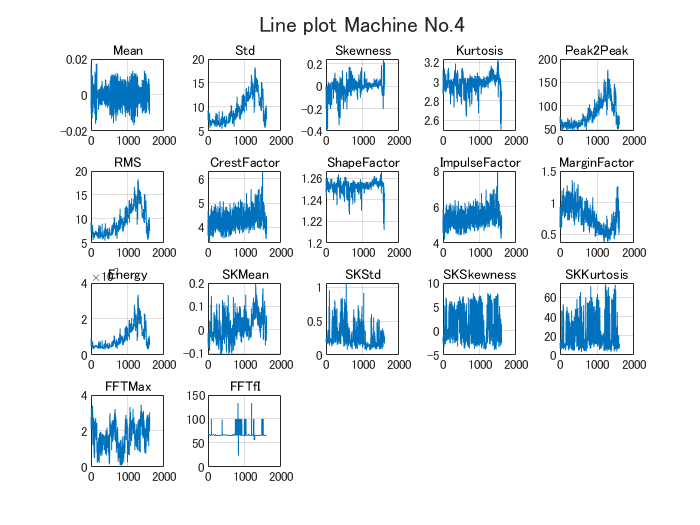

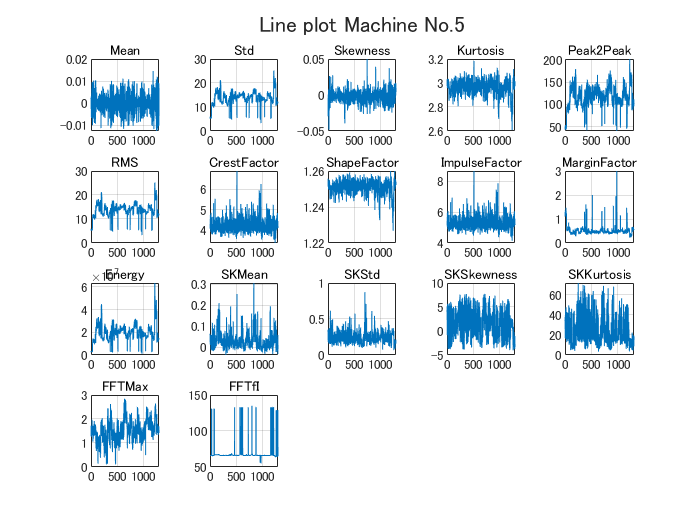

features = sortrows(features,'xTime','ascend');
for bs = 2 :5
    tmp = features(features.BushingNo == bs, :); 
    figure;
    t = tiledlayout ('flow',"TileSpacing","compact");         %t=tiledlayout (4,4);
    title (t, "Line plot Machine No." + bs);   
    for i = 18:numel(tmp.Properties.VariableNames)
        nexttile;
        plot(tmp(:,i).(1));
        title(tmp.Properties.VariableNames(i))
        grid on;
    end
    saveas (gcf, "Line spinner" + bs, "png");    
    savefig ("Line spinner" + bs)
end

clear i j k t tmp bs;

## Histgram（データの分布確認）

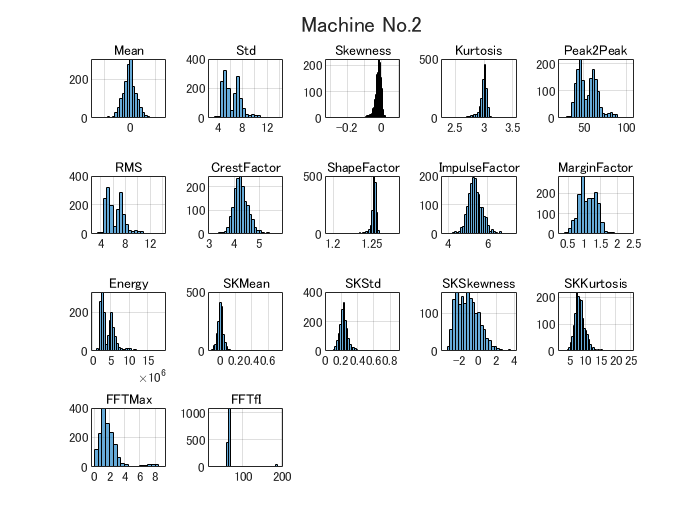

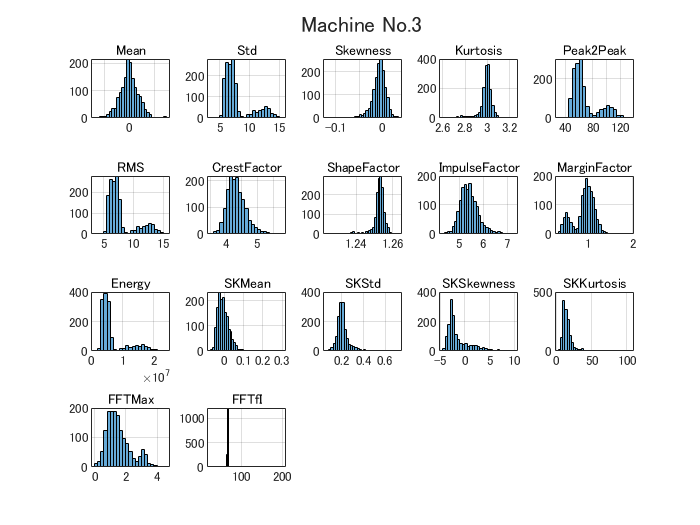

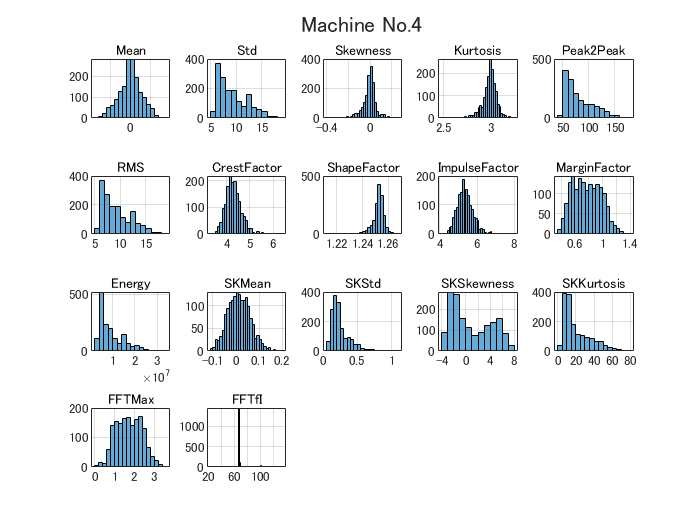

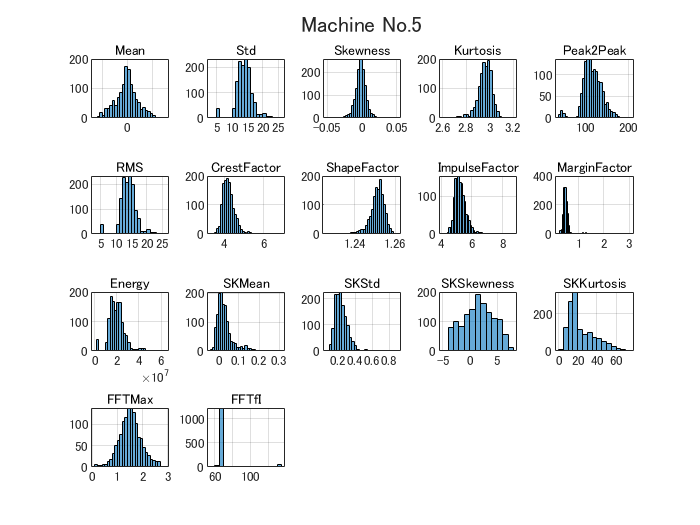

%nexttile;
% histgram (rD.L4,"FaceColor","m");
% title("L4");

for bs = 2 :5
    tmp = features(features.BushingNo == bs, :);
    figure;
    t = tiledlayout ('flow',"TileSpacing","compact");         %t=tiledlayout (4,4);
    title (t, "Machine No." + bs);
    for i = 18:numel(tmp.Properties.VariableNames)
        nexttile;
        histogram(tmp(:,i).(1));
        title(tmp.Properties.VariableNames(i));
        grid on;
    end
    saveas (gcf, "Histogram spinner" + bs, "png");    
    savefig ("Histogram spinner" + bs)
end

clear i j k t tmp bs;

## X,Y Scatter plot（Y=実時間）

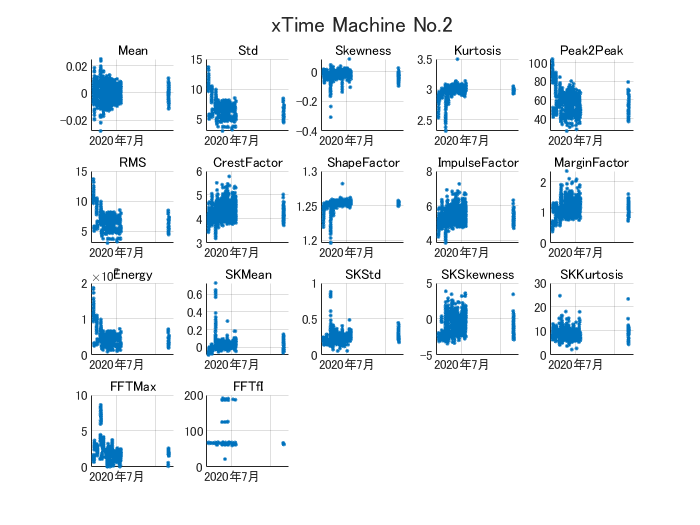

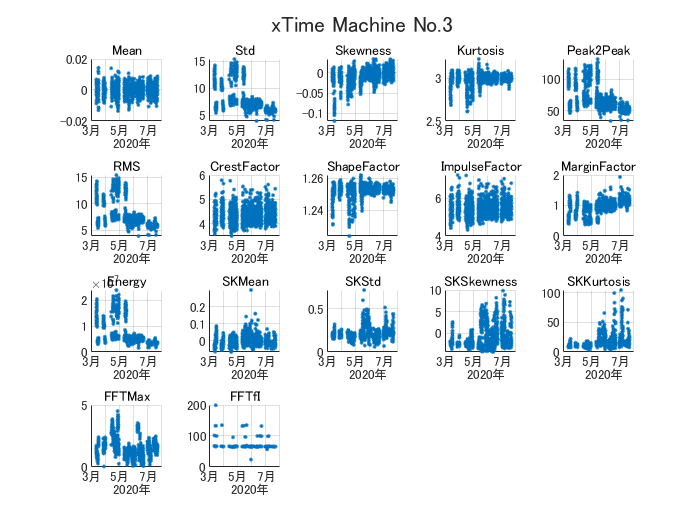

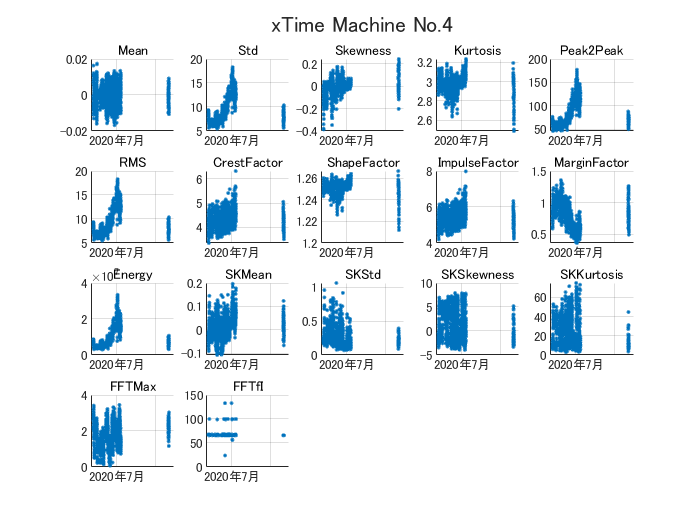

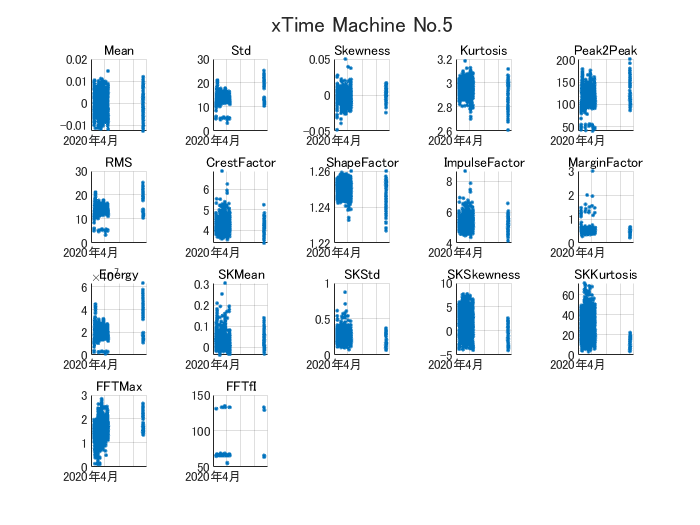

for bs = 2 :5
    tmp = features(features.BushingNo == bs, :);
    figure;
    t = tiledlayout ('flow',"TileSpacing","compact");         %t=tiledlayout (4,4);
    title (t, "xTime Machine No." + bs);
    for i = 18:numel(tmp.Properties.VariableNames)
        nexttile;
        scatter(tmp.xTime,tmp(:,i).(1),'.');
        title(tmp.Properties.VariableNames(i));
        grid on;
    end
    saveas (gcf, "Scatter xTime spinner" + bs, "png");    
    savefig ("Scatter xTime spinner" + bs)
end

clear i j k t tmp bs;


## X,Y Scatter plot（Y＝スピナー時間）

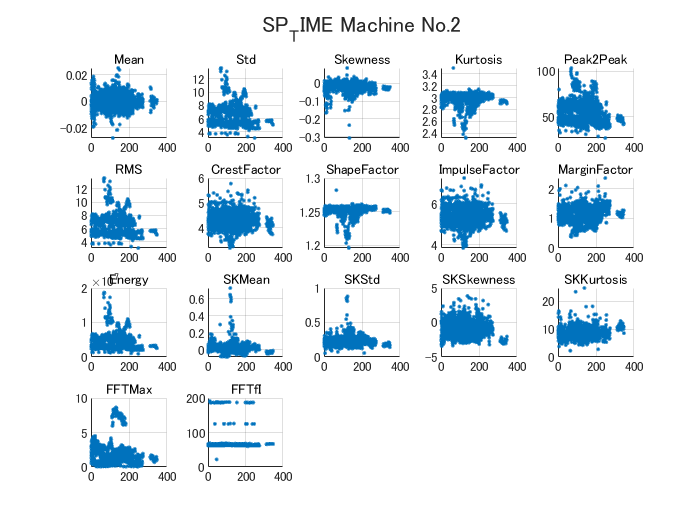

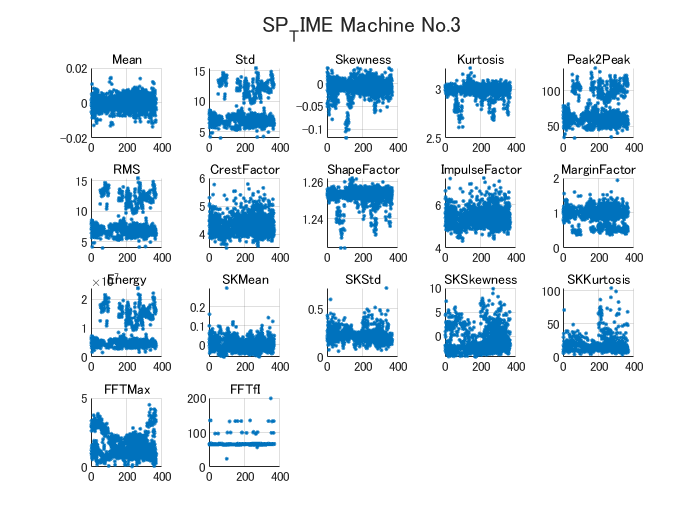

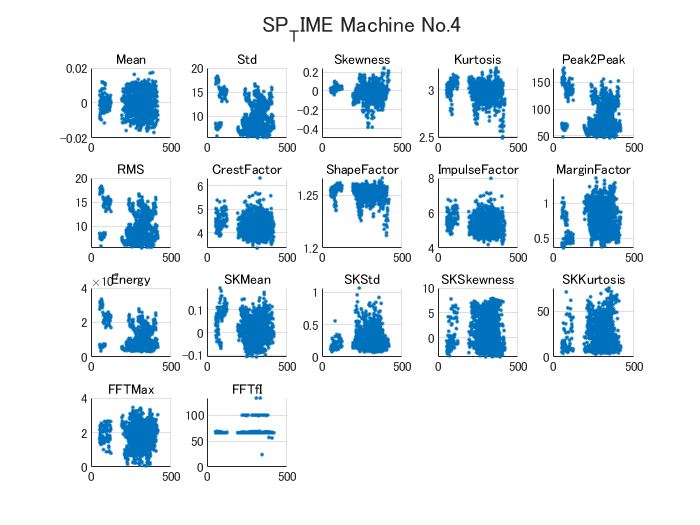

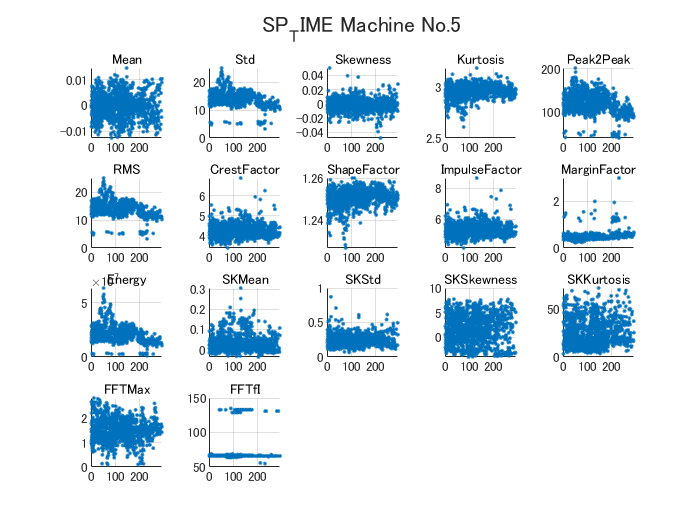

for bs = 2 :5
    tmp = features(features.BushingNo == bs, :);
    figure;
    t = tiledlayout ('flow',"TileSpacing","compact");         %t=tiledlayout (4,4);
    title (t, "SP_TIME Machine No." + bs);
    for i = 18:numel(tmp.Properties.VariableNames)
        nexttile;
        scatter(tmp.SP_TIME,tmp(:,i).(1),'.');
        title(tmp.Properties.VariableNames(i))
        grid on;
%               scatter(features.SP_TIME,features(:,i+j).(1),"blue",'.');
%                scatter(tmp.xTime,tmp(:,i+j).(1),'.');
%                gscatter(features.xTime,features(:,i+j).(1),features.BushingNo);
    end
    saveas (gcf, "Scatter SP_TIME spinner" + bs, "png");    
    savefig ("Scatter SP_TIME spinner" + bs)
end

clear i j k t tmp bs;

features = sortrows(features,'Std','ascend');

features(1:34,:) = [];

features = sortrows(features,'SKMean','descend');

features(1,:) = [];

% tmp = features(features.Std<=5 & features.BushingNo == 2, :);
% a = (features.Std'<15 & features.BushingNo== 2);
% tf = (T.BMI <= 25);
